# ECE 1395 Project:

## Chess Evaluator

**Names:** Benjamin Bryla, Gabriel Yeniceri

clear; clc

## Thresholds

%Positin is classified as equal if within
IsEqual=75; %Position is equal if magnitude is inbetween +# and -#

%If checkmate exists, force evaluation to be
CheckmateThreshold=1000; %  [M-2] -> [-1000]

%Used as seed for RNG
RNG=123;


# Data Preprocessing:

#### Loading Data:

%Read filename and input into array
filename = "input\dataset_eval.csv";

%Options for getting CSV file read correct
options=detectImportOptions(filename);
options=setvartype(options,["Var2","Var4"],"string"); %Force strings, Eval: M1 does not give NaN value anymore
options.Delimiter = ',';
options.VariableNamingRule = 'preserve';

Data = readtable(filename, options);

#### Split data into Position and Evaluation

FEN = Data{:,2};
Eval = Data{:,4};

Column 1 and 3 are unneccessary. Column 1 is the game #, this will not influence training in any way. Column 3 is best move, the scope of the project will no longer contain the best move, instead it only contains evaluation. 

Cleanup

clearvars options filename Data

## Evaluation Pre-Process:

This part of the pre-processing will deal with the evaluation output. 

- If there is checkmate on board (denoted by M # or M- #) the evaluation is going to be set to some variable defined above. 

- The evaluation of each position is given relative to who's turn it is, + is winning for whoever's turn it is. The evaluation will be changed to absolute relative to white. + is winning for white no matter who's turn it is.

- The evaluation is also going to be turned into classes based on some threshold defined above, -1 black winning, 0 is within threshold, 1 white winning. Adding 2 to every column will change it to 1 is black winning, 2 is equal, 3 is white winning. 

%Modify mate on boards
is_M = contains(Eval(:),'M'); %If Mate is on Board
is_EvalMinus = ~contains(Eval(:),'-'); %If evaluation contains a - 

IsMate=((is_EvalMinus-0.5)*2).*is_M*CheckmateThreshold; %Mating Threat new evals
IsMateShort=IsMate(IsMate~=0);

%Change eval from Relative based on turn, to Absolute based on White
is_WhiteTurn = contains(FEN(:),'w'); %If is White's Turn

EvalAbsolute=(is_WhiteTurn-0.5)*2;

%Change Checkmate in # to Checkmate Threshold
Eval(is_M)=IsMateShort; 
%Change Relative eval to Absolute Eval
Eval=str2double(Eval);
Eval=Eval.*EvalAbsolute;

%Create Discrete Evaluation
function EvalDiscrete=DiscreteEval(Eval,Threshold)
Greater= Eval>=Threshold;
Less= Eval<=-Threshold;

EvalDiscrete=Greater-Less;
end

EvalDiscrete=DiscreteEval(Eval,IsEqual);


Cleanup

clearvars is_M is_M is_EvalMinus IsMate IsMateShort EvalAbsolute CheckmateThreshold Greater Less

## Bitboard Pre-Process:

Converts FEN notation to Bitboard Representation

%Splits bitboard into Board, and Extras
SplitFEN=split(FEN); %Index 1 is Board, Index 2-6 is extra information
%Board Split
Board=split(SplitFEN(:,1),'/');

BoardExtra=SplitFEN(:,2:end);

#### Written:

At this point we have the board, m x 8 string, each column represents a chess board column. BoardExtra is split up into 5 columns, turn, Castling rights, Enpassant rights, half move clock, full move number. 

cleanup

clearvars SplitFEN

## Bitboard Creation

FEN to Piece Board function. Takes in the board split from above

%Create a Piece Board
function PieceBoard=FEN2Piece(Board)
    PieceBoard=zeros(1,8*8);
    L=strlength(Board);
    for dataNum=1:height(Board) %For every data set
        CurrBoard = Board(dataNum,:);
        rowIndex=1;
        for column=1:8 %For every column of chess board
            CurrRow = CurrBoard(column);
            for row=1:L(dataNum,column) %For the rows of the chess board
                charRow=CurrRow{1}(row);
                if isstrprop(charRow, 'digit') %If number is found add it's value to index do not update the piece board
                    rowIndex = rowIndex + str2double(charRow);
                else %If character is found
                    PieceBoard(dataNum,rowIndex)=charRow; %If char is found, set char
                    rowIndex=rowIndex+1; %Increment
                end
            end
        end
    end
end

Piece to Bit Board function

function BitBoard=Piece2Bit(Piece)
%List of pieces
pieceList='pbnrqkPBNRQK';
for m=1:height(Piece)
    BitBoard=false(height(Piece),8*8*12);
    for squareIndex=1:64 %Check every square for if it contains a piece
        for pieceIndex=1:12
            if pieceList(pieceIndex)==Piece(squareIndex)
                BitIndex=squareIndex+64*pieceIndex-64; %Calculate index of the bitboard square
                BitBoard(BitIndex)=1; %And set to true
            end
        end
    end
end
end

Converts the Board representation into Bitboards

%Number of data points to use
m=height(Board);
%m=5000;

%Setup Empty Arrays
Data=Board(1:m,:);
PieceBoard=zeros(height(Data),8*8);
BitBoard=false(height(Data),8*8*12);

%Convert to piece board
tic
for i=1:m
    PieceBoard(i,:)=FEN2Piece(Board(i,:));
    BitBoard(i,:)=Piece2Bit(PieceBoard(i,:));
end
timeElapsed=toc
fprintf("Time to convert %d FEN to bitboard: %0.5f\n",m,timeElapsed)

%Convert to Char
PieceBoard=char(PieceBoard);
%Fill in Empty
PieceBoard(PieceBoard==0)='~';

Cleanup

clearvars Data timeElapsed i Board

## FEN Conversion Verification

Testing: Check current board state based on index

index=3651;
disp("index: "+index)
ShowBoard=reshape(PieceBoard(index,:),8,8)'; %Convert from Piece Board into 8x8
disp("Show the current board state")
disp(ShowBoard)

pieceList='pbnrqkPBNRQK';
for i=0:11 %Each Piece
    disp(pieceList(i+1))
    disp(reshape(BitBoard(index,64*i+1:64*i+64),8,8)') %Convert from Bit Board into 12x8x8
end

Cleanup

clearvars index ShowBoard disp i

Example at Index 285; Comparing Chess.com vs Matlab; The current board state in an array that represents the same boardstate as chess.com's FEN analysis. 

Data Set: Eval = -358: EvalDiscrete = -1 (black winning). 

Chess.com Evaluation -3.47, -1 (black winning) , depth 17, 3 seconds. This 100x scaling in the data set is used to removing the decimal. 

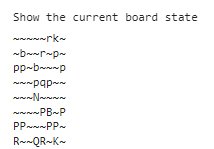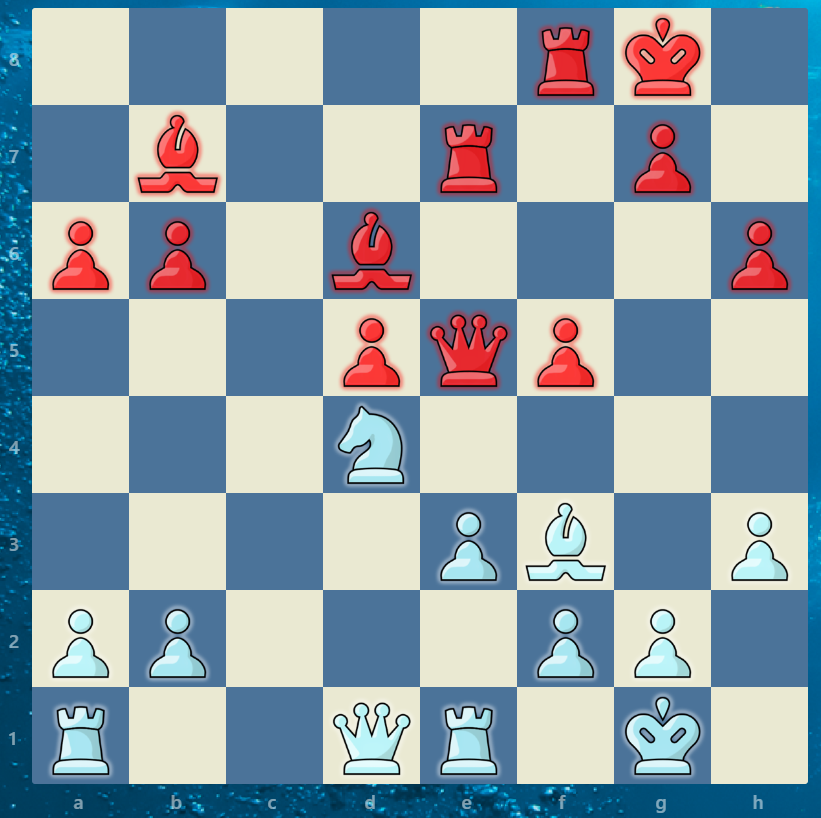

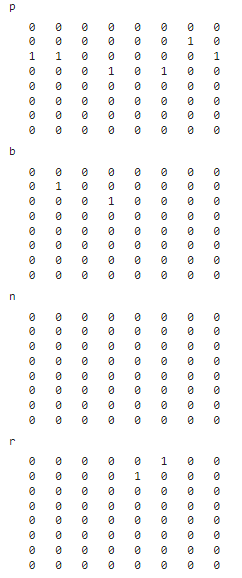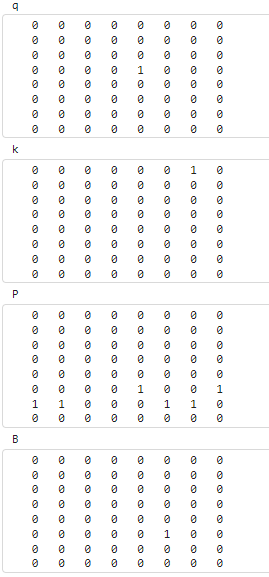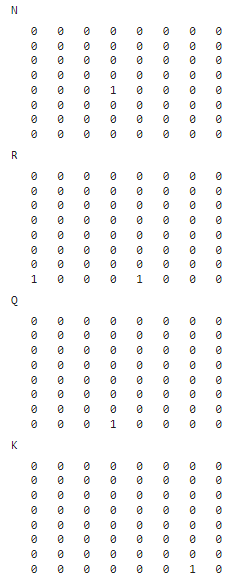

When looking at the bit board, it aligns with the location of pieces for FEN notation. Lowercase = Black pieces. Uppercase = White Pieces. The position is aligned with the standard chess board position. K is White's King, in both the bit board, piece board, and chess.com it is shown in the G1 square. p is Black's Pawns, the structure is the same in all 3 representations. n is Black's Knights, the bitboard is all 0's because black does not have a knight. 

## FEN Extra Data

FEN notation has 5 additional bits of information that need to be dealt with. 

It is split up into the BoardExtra variable, they were all separated prevously by the space demileter

Column 1: Who's turn it is. b=black, w=white

Will be represented by a 1=white, 0=black

is_WhiteTurn; %Already created when coverting from relative to absolute evaluation. 

Column 2: KQkq, Castling legality, K=White king side castle, Q=White Queen Side Caste. kq are same but for black;

can_Castle=zeros(height(BoardExtra),1);
%Can white castle King/Queen side
can_Castle(:,1)=contains(BoardExtra(:,2),"K");
can_Castle(:,2)=contains(BoardExtra(:,2),"Q");
%Can black castle King/Queen side
can_Castle(:,3)=contains(BoardExtra(:,2),"k");
can_Castle(:,4)=contains(BoardExtra(:,2),"q");

Column 3: En-Passant Rights, if a piece can enpassant, this is the square it can go to. 

1=Can EnPassant, 0=Cannot. This is unlikely to have many data points (417, ~0.12% total positions, 5175 games total, 417 positions even have it as an option), in addition it is not a critical portion of an evaluation, a true/false value should suffice for our use. Any non '-' value will be set to 1 for can en-passant. 

is_EnPassant=BoardExtra(:,3)~='-';

Column 4: Half-Move Clock. Counts up by 1 every half move (white OR black moves), resets to 0 every time there is a, capture, or pawn move. This is from the 50 move rule in chess where if neither side captures, or makes a pawn move the game is a draw;

Convert to Double: 

HalfMove=str2double(BoardExtra(:,4));

Column 5: Full Move Counter. after white AND Black has moves, ticks up by 1. How many moves the game has been;

Convert to Double: 

FullMove=str2double(BoardExtra(:,5));

Full Bitmap

BitBoardFull=[BitBoard,is_WhiteTurn,can_Castle,is_EnPassant,HalfMove,FullMove];

Here we have the full BitBoard

Index References:

1-768 = Bitboard of piece locations, 12x8x8 in 'pbnrqkPBNRQK' piece order

769: Who's turn it is. 1=White, 0=Black

770-773: Castling Rights. White: King Queen side, Black: King Queen side, 1=Yes Castle

774: Is En-Passant Legal, 1=Yes

775: Half Move Clock

776: Full Move Counter

cleanup

clearvars can_Castle BoardExtra FullMove HalfMove is_EnPassant m 

# Linear Regression Implementation

Ben is Implementing this portion

Paremeters

alpha=0.01;
num_iters=200;

Split into Test & Training data set

%Set RNG & Split
rng(RNG)

Training Time: 25.8

SplitCutoff=height(Eval)*0.1; % 10% is Testing
Split=randperm(height(Eval));

%Define Test
X_Test=BitBoardFull(Split(1:SplitCutoff),:);
y_Test=Eval(Split(1:SplitCutoff),:);
%Define Validate
X_Train=BitBoardFull(Split(SplitCutoff+1:end),:);
y_Train=Eval(Split(SplitCutoff+1:end),:);

Train a model

rng(RNG)

tic;
model=fitlm(X_Train,y_Train,'linear'); %Linear Regression Model
time=toc;
fprintf("Training Time: %0.1f",time)

Calculate accuracy

Also check with Normal Equation

function theta = normalEqn(X,y)
    %Normal Equation

Accuracy: 67.8%


    theta = ((pinv(X'*X))*X')*y;
end

Normaltheta = normalEqn(X_Train,y_Train);
y_predict=X_Test * Normaltheta;

%Convert into classes
y_predictDiscrete=DiscreteEval(y_predict,IsEqual);
y_TestDiscrete=DiscreteEval(y_Test,IsEqual);

Accuracy: 67.8%


%Accuracy
accuracy= mean(y_predictDiscrete==y_TestDiscrete);
fprintf("Accuracy: %0.1f%%\n",accuracy*100)

y_predict=predict(model,X_Test);

White's Turn Weight: 1.3986



%Convert into classes
y_predictDiscrete=DiscreteEval(y_predict,IsEqual);
y_TestDiscrete=DiscreteEval(y_Test,IsEqual);
%Accuracy
accuracy= mean(y_predictDiscrete==y_TestDiscrete);
fprintf("Accuracy: %0.1f%%\n",accuracy*100)

Evaluate outcome

Check the weight each piece has on each square. 

BitThetas=table2array(model.Coefficients);

p


Average Piece Weight: -1.1103


         0         0         0         0         0         0         0         0
   -0.8817   -1.0925   -0.6978   -0.5375   -0.7118   -1.1609   -1.3216   -0.9430
   -0.9564   -1.0200   -0.9979   -0.9340   -1.0838   -0.9236   -1.2683   -1.0873
   -0.8527   -1.1506   -0.8055   -1.0712   -1.0026   -0.9836   -1.1135   -0.7451
   -1.0422   -1.2777   -0.8891   -1.1733   -1.4946   -1.1689   -1.4576   -1.2830
   -1.4457   -1.9564   -1.7684   -2.1953   -1.8461   -2.0852   -2.3155   -2.1042
   -3.1881   -2.9693   -2.5612   -3.6959   -2.7989   -2.3829   -2.6023   -2.0165
         0         0         0         0         0         0         0         0



b


Average Piece Weight: -2.7649


   -2.5089   -2.5048   -2.4572   -3.1034   -2.2111   -2.5878   -4.1537   -2.6727
   -2.8237   -2.9103   -3.0465   -2.6822   -2.9438   -2.7101   -3.2222   -2.6789
   -2.7665   -3.0466   -2.6740   -3.0490   -3.0861   -3.1810   -3.0146   -2.6145
   -2.6377   -2.8103   -3.0614   -3.0378   -3.3083   -2.9269   -2.8922   -2.8433
   -2.0122   -3.0001   -3.3463   -3.2687   -3.0379   -3.4626   -2.9177   -3.0186
   -2.7784   -3.4602   -2.6604   -3.2688   -2.7175   -2.5407   -3.2902   -3.2780
   -2.2216   -2.9866   -2.9104   -1.4454   -2.3990   -3.4342   -2.7724   -3.4834
   -1.4915   -2.2702   -0.6408   -1.8977   -2.3751   -1.7653   -3.3494   -1.2862



n


Average Piece Weight: -2.5502


   -1.2994   -1.9473   -1.3105   -1.9709   -2.0541   -1.8964   -1.8964   -2.1516
   -2.4727   -2.0328   -2.1119   -2.3352   -2.4333   -2.6418   -2.1024   -1.9174
   -1.9453   -2.4165   -2.6162   -2.9781   -2.4988   -2.5729   -2.7055   -2.2549
   -2.1516   -2.0522   -2.6070   -2.6463   -2.7937   -3.0574   -2.3317   -2.3946
   -2.9407   -2.6245   -3.2409   -3.2861   -2.8415   -3.0838   -2.8203   -3.2328
   -2.9627   -2.8297   -3.1345   -3.4251   -2.7176   -3.6651   -3.0445   -3.4330
   -1.7724   -2.7638   -3.5172   -2.8548   -2.9954   -2.9668   -3.9478   -2.7692
   -2.0057   -2.1748   -3.3112   -2.1109   -2.4091   -1.7891   -2.4227   -1.5235



r


Average Piece Weight: -4.0591


   -3.4672   -3.6593   -3.9679   -3.9372   -4.0619   -3.7513   -3.8853   -3.3485
   -3.3807   -3.5360   -3.7772   -3.7238   -3.7658   -3.5904   -3.0810   -4.1988
   -3.3702   -3.7628   -3.2162   -3.4194   -4.0631   -3.6196   -3.6311   -4.1280
   -3.9759   -3.4631   -3.8807   -4.1656   -4.4734   -4.0282   -4.1348   -4.2913
   -5.1202   -4.5721   -4.7316   -4.7258   -4.3686   -3.8807   -4.0183   -4.8885
   -4.6909   -4.9221   -4.9851   -3.9994   -4.3352   -4.4936   -4.4155   -3.7680
   -4.5280   -4.3221   -4.5701   -4.9903   -4.0552   -4.6333   -4.7413   -4.9214
   -4.3954   -4.1151   -4.0799   -3.5376   -3.8169   -3.2279   -3.0681   -4.1102



q


Average Piece Weight: -6.2439


   -5.5928   -5.8297   -5.4893   -6.1125   -5.7549   -5.7707   -5.3026   -6.5313
   -6.3724   -5.8967   -6.3274   -5.9717   -6.2617   -5.9773   -6.0262   -6.8178
   -6.3916   -6.2613   -6.3750   -6.1207   -5.9590   -6.2137   -6.3261   -6.5557
   -6.2583   -6.1732   -6.1041   -6.4791   -6.5697   -6.4686   -6.1945   -6.0759
   -6.1233   -6.5557   -6.2325   -6.5296   -6.9598   -7.0043   -7.0323   -6.5351
   -6.3182   -6.8333   -6.9782   -6.5086   -6.6396   -7.2985   -7.0770   -7.9438
   -6.1381   -6.1576   -6.0337   -6.9993   -5.9069   -6.3716   -4.8405   -6.7633
   -5.2341   -5.0064   -5.9074   -5.2006   -5.4792   -6.3098   -5.9610   -6.1679



k


Average Piece Weight: -0.274


   -0.9020   -0.1434   -0.1292    0.4742    0.3364   -0.0677   -0.2621   -0.0395
   -0.0445   -0.0111    0.1625    0.4821    0.1533   -0.1125   -0.2412   -0.1665
   -0.1409    0.6790    0.6536    0.2276    0.2187    0.3343    0.0220   -0.0175
   -0.5754   -1.2243   -1.4193   -0.1539    0.0475   -0.4617    0.0971    0.0435
    0.1743   -1.0272   -0.3743   -0.7896   -0.3344   -1.2163   -0.9480    0.6197
    1.6991   -1.1916   -1.1323   -1.0671   -0.0882   -0.2555   -1.2096   -0.4280
    1.5142    0.3331    0.2392   -1.7171   -1.8610   -0.8549   -2.3959    1.2116
   -0.2672   -2.4742         0   -2.5433   -1.5394    0.3346    1.3302    0.9041



P


Average Piece Weight: 1.0323


         0         0         0         0         0         0         0         0
    2.5611    2.1146    2.8760    2.9061    2.7070    3.2392    2.7843    1.7436
    2.0914    1.7875    2.0664    1.8855    1.4563    1.8558    2.1397    1.9382
    1.7108    1.0029    0.9910    1.0749    1.1245    1.2699    0.9719    0.7552
    0.8656    0.8736    0.9163    1.0651    1.0026    0.8738    0.8873    0.7601
    0.9507    0.9624    0.8611    0.7701    1.0512    0.7739    1.0655    0.8348
    0.8407    0.9856    0.7051    0.4529    0.7208    0.8759    1.1380    0.7815
         0         0         0         0         0         0         0         0



B


Average Piece Weight: 2.8916


    2.1607    3.4014    2.6311    3.3175    2.8417    1.0706    5.3438    3.1325
    2.0535    2.9440    2.6842    2.5485    2.8421    2.5708    2.5921    3.2021
    2.5058    2.3502    2.4812    3.7461    2.9294    2.3993    4.0067    3.1770
    3.2091    3.1926    3.2643    3.2351    3.3267    2.7933    2.9851    2.1095
    3.1745    2.9942    3.0322    3.4447    2.9624    3.1455    2.6196    2.8585
    2.7668    2.9710    3.1496    3.0492    3.0706    2.9535    2.8016    2.5976
    2.9581    3.0453    3.1055    2.8067    2.8947    2.8057    3.0577    2.4733
    3.0449    2.9985    2.6217    2.1702    2.4896    2.5089    2.6116    2.8278



N


Average Piece Weight: 2.5067


    2.1192    3.9267    1.6960    2.6115    2.0465    2.6677    1.6649    2.3336
    2.2671    1.9080    3.0164    2.5344    3.0377    2.8110    1.8877    2.8329
    3.4636    3.1242    2.7470    3.5965    3.3170    3.4205    3.1355    2.5039
    2.1159    2.7980    2.7266    3.2259    3.0016    3.5533    2.7071    2.4297
    2.3115    2.6869    2.7956    2.7395    2.8222    2.7308    2.8900    2.3591
    2.0205    2.0864    2.6068    2.7500    2.6227    2.6370    2.4705    1.9411
    1.3245    2.4080    2.8191    2.4565    2.5812    1.4936    2.1074    2.6099
    1.5738    1.9534    1.6836    1.3714    2.5047    2.0770    2.0351    1.7297



R


Average Piece Weight: 4.0397


    4.2115    4.3228    4.2833    3.9701    3.4398    3.3953    4.1950    3.7515
    4.6425    4.4789    4.8058    4.4770    4.2898    4.4881    4.2478    4.8804
    4.6020    4.4895    4.5431    4.5595    4.0965    4.2721    4.2233    4.1288
    4.2722    4.2166    4.2980    3.6603    3.9220    3.6439    4.1057    4.0030
    3.8368    4.0544    4.2085    4.0971    4.1364    3.9001    4.5193    3.9081
    3.2336    3.6514    4.0380    3.4642    3.7139    3.6764    3.9742    4.0027
    3.3694    3.9812    3.5732    3.6621    4.0133    3.8318    3.4204    4.8319
    3.5289    3.8100    3.9400    3.9813    4.0455    3.7733    4.1190    3.3293



Q


Average Piece Weight: 6.2058


    6.2392    4.8304    4.1526    5.2786    5.1947    5.4293    5.9734    5.8080
    6.6900    5.6823    7.0460    6.1785    7.2324    6.8775    5.1999    7.1863
    6.2365    6.1285    6.8800    6.8498    6.8376    7.1289    7.3195    7.3876
    6.3010    6.2225    6.4095    6.4089    6.6819    6.6611    6.5887    6.9273
    6.2628    5.9948    6.0638    6.4530    6.4431    6.5634    6.3757    6.1110
    6.2013    6.2272    6.1808    6.2623    6.3166    6.3505    6.3359    6.2901
    5.8635    5.7503    6.2501    6.2689    6.2291    6.3548    5.5107    6.6768
    6.0776    5.9131    5.7001    6.1151    6.1655    5.5117    4.9932    5.3886



K


Average Piece Weight: -2.2333


         0   -2.3962   -1.3056   -1.0649   -6.2883   -4.6060   -3.2577   -0.0046
   -1.7516   -1.8226   -0.6656   -0.0541   -2.0250   -3.4025   -3.7211   -2.4402
   -1.7171   -0.9504   -0.7888   -1.9136   -1.4951   -1.7515   -1.8319   -3.0372
   -1.2051   -2.2435   -0.9418   -1.6523   -2.0992   -2.0376   -2.0317   -2.4657
   -2.4592   -2.9945   -2.8657   -2.1541   -2.0370   -2.3944   -2.5308   -3.8650
   -2.2586   -2.5657   -2.5210   -2.7425   -2.1375   -2.3519   -2.4627   -2.7488
   -2.7076   -2.2830   -2.6968   -2.6413   -2.6719   -2.2238   -2.5803   -2.6236
   -1.3298   -1.8106   -2.1104   -2.8465   -2.9613   -2.8060   -2.1693   -2.4109



disp("White's Turn Weight: "+BitThetas(770,1)/100)
BitThetas=BitThetas(2:769,1);

pieceList='pbnrqkPBNRQK';
for i=0:11 %Each Piece
    disp(pieceList(i+1))
    disp("Average Piece Weight: "+mean(BitThetas(64*i+1:64*i+64,1)/100))
    disp(reshape(BitThetas(64*i+1:64*i+64,1),8,8)'/100) %Convert from Bit Board into 12x8x8
end

Maybe check correlation with a Piece Square Table

Any positive values means that White is winning, Negative values means Black's winning

Looking at the average weight each piece roughly aligns with the standard value of pieces.

From what I can tell the pawn weights are biased taking only the mean since as pawns get further and closer to promotion the weight increases to around 1/2 the value of a queen, 1 square from promotion. This extra weight as pawns are more advanced is expected because a pawn that threatens promotion is an advantage for whoever has the pawn. The top and bottom rows are all 0's for pawns because they cannot be on that square in the first place. 

The weights also accurately represent how although the standard convention of the knight being the same value as the knight, in practice the bishop has a slight advantage, ranging from 3 to 3.25, this difference can be seen in the weights of the two pieces. 

The weight for the rook is around 1.55x that of the knight for white, this is around the expected 5/3, 1.66x from the standard convention, this value of pieces is still within a reasonable range. 

The weight for the queen is far less than I expected, with only being 1.5x that of the rook, or 2.4x that of the knight. these values should be 1.8x and 3x respectively. I predict this is due to the queen's power comes from how it can go around the board and threaten tactics while a linear regression is only able to evaluate the value of pieces

The evaluation of the king is biased towards endgames where the king is an active piece, in a middle game or early game it is nearly impossible for a king to be on the other side of the board, and in a majority of positions the king will be in the starting position or castled, the weights for king that is not within 1 square of being castled, or starting square is likely to not be in the training set many times outside of an endgame. 

White's Turn: 1.39, Having it be a player's turn is generaly known as a 0.3 advantage, around 1/3 of a pawn. In the linear regression model the turn advantage was much higher than expected. This may be due to in the training set where tactics exist and if it is missed then there is a major change in the rating, this would put a much higher priority onto who's turn it is. 

Observing the normal equation's result it is approximately the same as the linear regression model, this means that the linear regression is likely to have worked. 

# CNN Implementation

# Evaluation